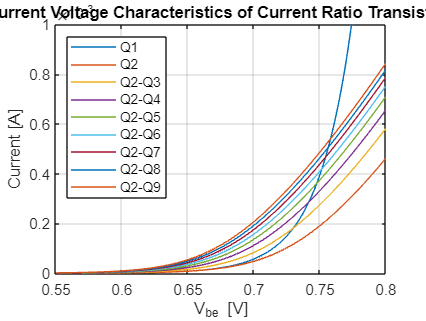

data1 = load('starter_kit_1.txt');


data2 = load('starter_kit_2.txt');
data3 = load('starter_kit_3.txt');
data4 = load('starter_kit_4.txt');
data5 = load('starter_kit_5.txt');
data6 = load('starter_kit_6.txt');
data7 = load('starter_kit_7.txt');
data8 = load('starter_kit_8.txt');

vbe = data1(:,2);
r1 = data1(:,3);
q1 = data1(:,4);

r2 = data2(:,3);
r3 = data3(:,3);
r4 = data4(:,3);
r5 = data5(:,3);
r6 = data6(:,3);
r7 = data7(:,3);
r8 = data8(:,3);

figure;
plot(vbe,q1,'-')
hold on
plot(vbe,[r1,r2,r3,r4,r5,r6,r7,r8],'-')
hold off
grid on
xlim([0.55, 0.8]);
ylim([0, 1e-3]);
xlabel('V_{be} [V]');
ylabel('Current [A]');
title('Current Voltage Characteristics of Current Ratio Transistors')
legend('Q1', 'Q2', 'Q2-Q3', 'Q2-Q4', 'Q2-Q5', 'Q2-Q6', 'Q2-Q7', 'Q2-Q8', 'Q2-Q9', 'location', 'northwest')

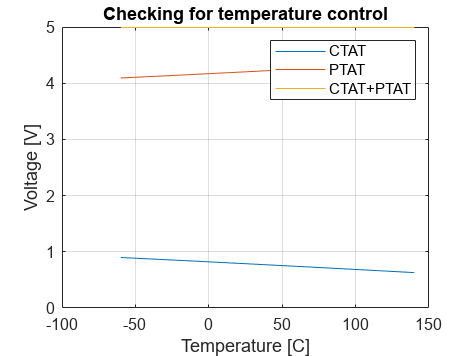

%%% this one shows the stablility and not allowing
%%% the temperature to change the output voltage
data = load('Temperature_PTAT_CTAT.txt');
VB2 = data(:,2);
VR2 = data(:,3);
temp = linspace(-60, 140, 21);
CTAT = VB2-VR2;
PTAT = VR2;
vout = CTAT+PTAT;
figure;
plot(temp,[CTAT, PTAT, vout])
grid on
xlabel('Temperature [C]')
ylabel('Voltage [V]')
title('Checking for temperature control')
legend('CTAT','PTAT', 'CTAT+PTAT')

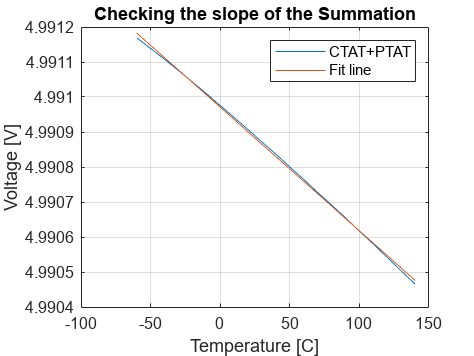

[~, ~, m, b, ~] = linefit(temp, vout, 1e-2);
figure;
plot(temp,vout)
hold on
plot(temp,m*temp+b)
hold off
grid on
xlabel('Temperature [C]')
ylabel('Voltage [V]')
title('Checking the slope of the Summation')
legend('CTAT+PTAT', 'Fit line')

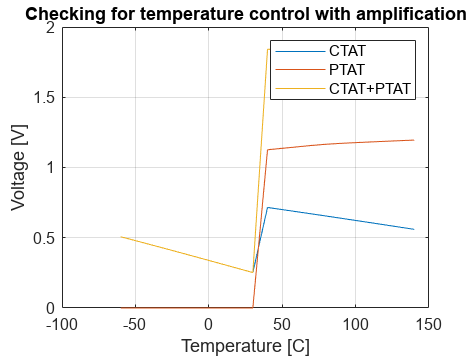

%%% this one shows the stablility and not allowing
%%% the temperature to change the output voltage
data = load('amplified_vout.txt');
VB2 = data(:,2);
VR2 = data(:,3);
temp = linspace(-60, 140, 21);
CTAT = VB2-VR2;
PTAT = VR2;
vout = CTAT+PTAT;
figure;
plot(temp,[CTAT, PTAT, vout])
grid on
xlabel('Temperature [C]')
ylabel('Voltage [V]')
title('Checking for temperature control with amplification')
legend('CTAT','PTAT', 'CTAT+PTAT')

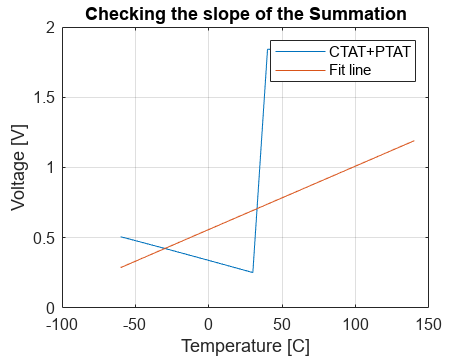

[~, ~, m, b, ~] = linefit(temp, vout, 1e-2);
figure;
plot(temp,vout)
hold on
plot(temp,m*temp+b)
hold off
grid on
xlabel('Temperature [C]')
ylabel('Voltage [V]')
title('Checking the slope of the Summation')
legend('CTAT+PTAT', 'Fit line')

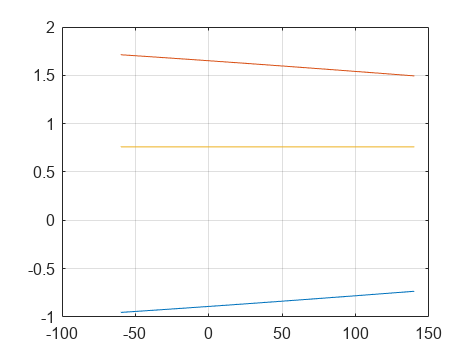

clear;
temp_data = load('help2.txt');

vq2 = temp_data(:, 2);
vq1 = temp_data(:, 4);
vb = temp_data(:, 3);

PTAT = vq1-vq2;
CTAT = vq2;
vout = PTAT+CTAT;
temp = linspace(-60, 140, 21);
plot(temp, [PTAT, CTAT, vout]);
grid on